Initially I played with the 2nd state model representation, i tried to control Va and gamma, as with these variables its possible to recreate an airplane route (airplane's gravity center) as it would be seen by a person aligned with the horizon, using as reference the initial point of the aircraft when the MPC starts to act. 

### SHAPING A MANEUVER

In the next section a maneuver, i.e. references of Va and Gamma v/s time, in another section the maneuver is recovered in a plane aligned with the horizon doing the proper transformation. 

clear
clc

time_res=.1; %time resolution, in seconds
dur_m=0; %total maneuver duration (to update)

% Define first maneuver (this maneuver is a stepwise point tracking maneuver):
dur_s=3; %duration in secs
va_points=[10 12 14 16 18 20];
gamma_points=[-pi/16 -pi/16 -pi/16 -pi/16 -pi/16 -pi/16 ];
va_imp=1; % importance of tracking va in this maneuver?
gamma_imp=1; % importance of tracking gamma in this maneuver?
for j=1:6
    if j==1
        va_ref=va_points(1,j)*ones(1,dur_s/time_res); %reference for Va 
        gamma_ref=gamma_points(1,j)*ones(1,dur_s/time_res); % reference for gamma
        va_l=va_imp*ones(1,dur_s/time_res); %importance of tracking va in this maneuver?
        gamma_l=gamma_imp*ones(1,dur_s/time_res); %importance of tracking gamma in this maneuver?
    else
        va_ref=[va_ref va_points(1,j)*ones(1,dur_s/time_res)];
        gamma_ref=[gamma_ref gamma_points(1,j)*ones(1,dur_s/time_res)];
        va_l=[va_l va_imp*ones(1,dur_s/time_res)];
        gamma_l=[gamma_l gamma_imp*ones(1,dur_s/time_res)];
    end
    dur_m=dur_m+dur_s;
end

% Define  second maneuver (oscillate pitch angle)
dur_s=10; %duration in secs

steps=linspace(0,dur_s,dur_s/time_res);

amp_osc=pi/3;% desired sinusoidal oscilation amplitude in y coord., in meters
period_osc=5; % desired time for a full loop
gamma_ref=[gamma_ref -pi/16+(amp_osc/2)*(sin(pi+2*pi*(1/period_osc)*steps))]; % reference for gamma

amp_osc=10;% desired sinusoidal oscilation amplitude in y coord., in meters
period_osc=5; % desired time for a full loop
va_ref=[va_ref 20+(amp_osc/2)*(sin(3*pi/2+2*pi*(1/period_osc)*steps))]; % reference for gamma

va_imp=1;
gamma_imp=1;
va_l=[va_l va_imp*ones(1,dur_s/time_res)];
gamma_l=[gamma_l gamma_imp*ones(1,dur_s/time_res)];
dur_m=dur_m+dur_s;

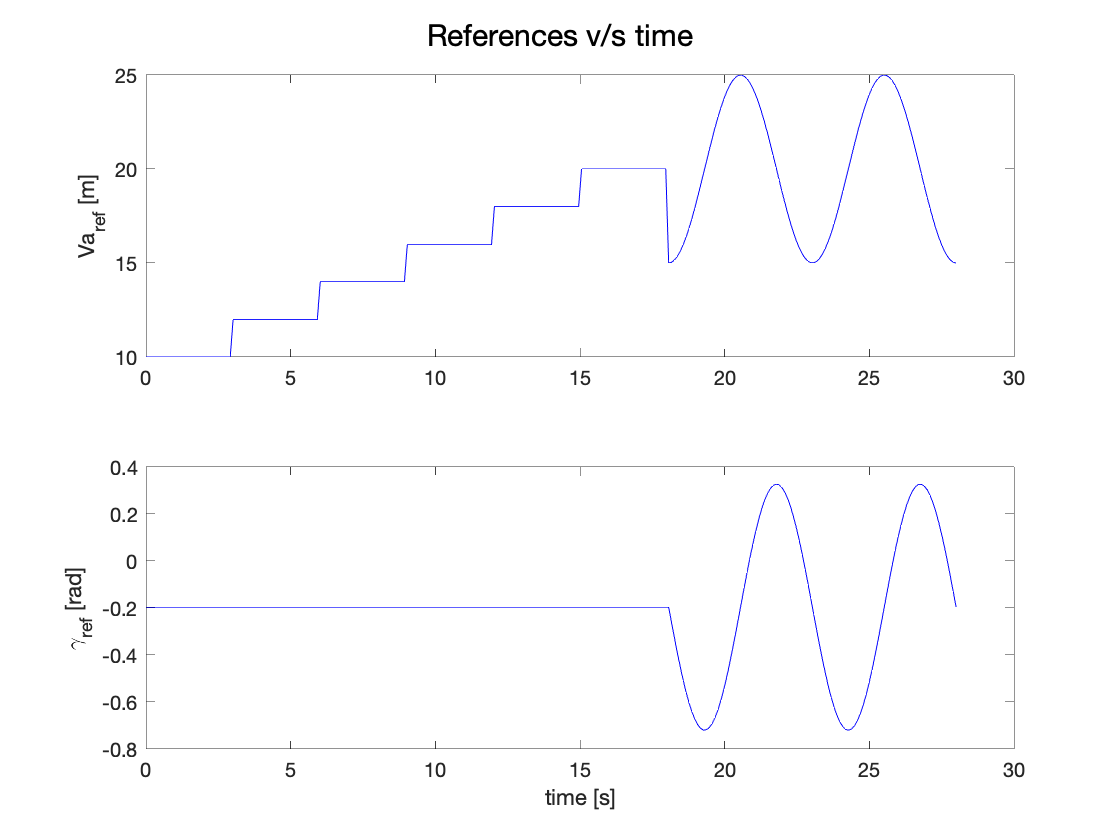

figure
sgtitle("References v/s time")
subplot(2,1,1)
plot(linspace(0,dur_m,dur_m/time_res),va_ref,'b')
ylabel("Va [m]")
ylabel("Va_{ref} [m]")
subplot(2,1,2)
plot(linspace(0,dur_m,dur_m/time_res),gamma_ref,'b')
%xlim([0,dur_m/time_res-1])
xlabel("time [s]")
ylabel("\gamma_{ref} [rad]")

Let's solve a MPC problem, assuming we know A and B perfectly, so solving the MPC from the first step is enough (there will be no discrepancies from reality)

x_ini=[12.4573, -0.888532, 1.38132e-08, -0.164542]';
N=dur_m/time_res; %horizon
%in this case we know the true model, so deterministic MPC will 
%deliver the optimal answer for every step, so only run it once 
[U,X,u]=MPC_perfect_information(x_ini,time_res,va_ref,gamma_ref, ...
    va_l,gamma_l,N);

u = -0.5236

Visualize solution:

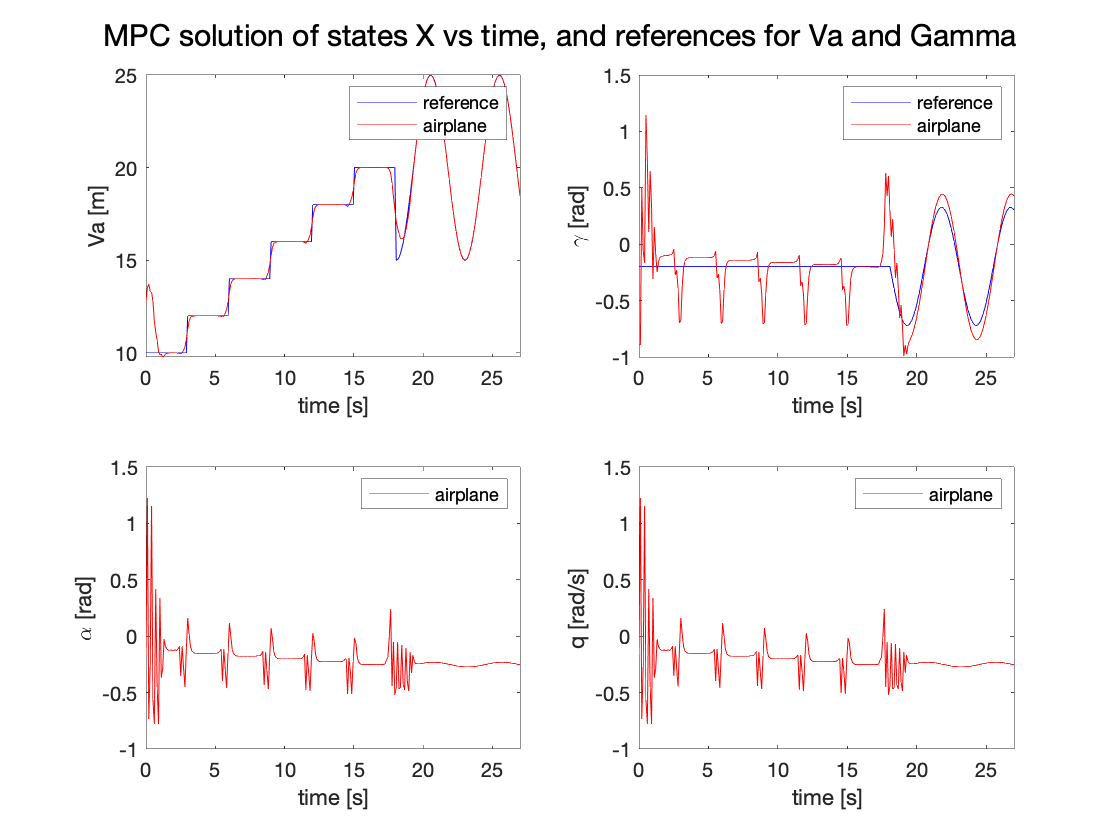

tf=dur_m-1; %tail (final step) is not important, as it can diverge
figure
sgtitle("MPC solution of states X vs time, and references for Va and Gamma")
subplot(2,2,1)
plot(linspace(0,dur_m,dur_m/time_res),va_ref,'b')
hold on
plot(linspace(0,dur_m,dur_m/time_res),X(1,2:end),'r')
xlim([0,tf])
legend('reference','airplane')
xlabel("time [s]")
ylabel("Va [m]")

subplot(2,2,2)
plot(linspace(0,dur_m,dur_m/time_res),gamma_ref,'b')
hold on
plot(linspace(0,dur_m,dur_m/time_res),X(4,2:end),'r')
xlim([0,tf])
legend('reference','airplane')
xlabel("time [s]")
ylabel("\gamma [rad]")

subplot(2,2,3)
plot(linspace(0,dur_m,dur_m/time_res),X(2,2:end),'r')
xlim([0,tf])
legend('airplane')
xlabel("time [s]")
ylabel("\alpha [rad]")

subplot(2,2,4)
plot(linspace(0,dur_m,dur_m/time_res),X(2,2:end),'r')
xlim([0,tf])
legend('airplane')
xlabel("time [s]")
ylabel("q [rad/s]")

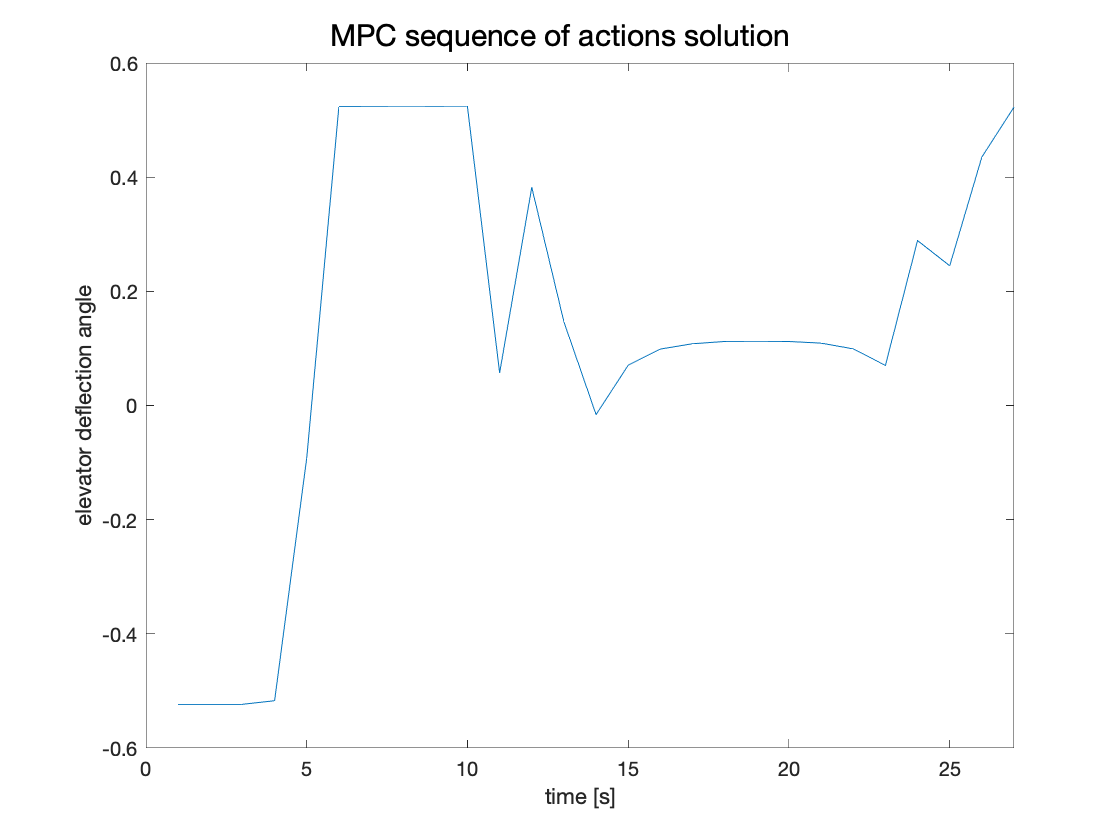

figure
sgtitle("MPC sequence of actions solution")
plot(U(1,2:end))
xlim([0,tf])
xlabel("time [s]")
ylabel("elevator deflection angle")

Reconstruct maneuver route as standing from aligned with the horizon axis

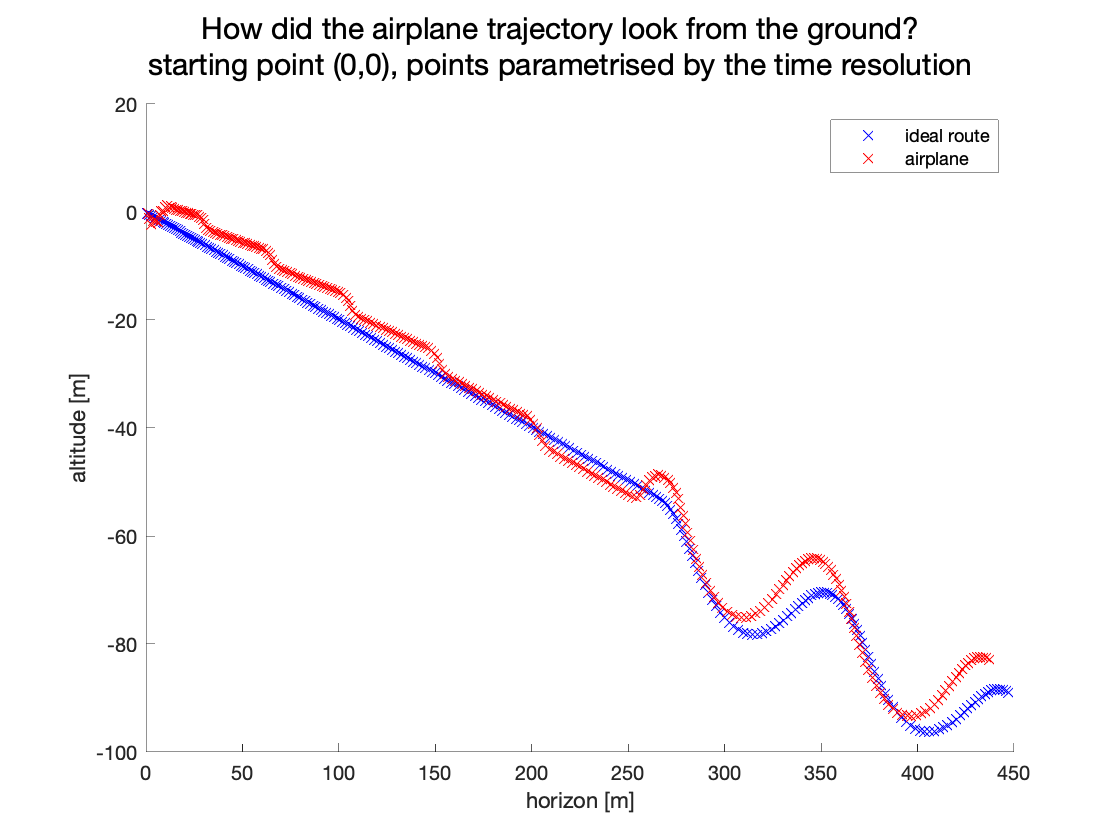

figure
sgtitle(["How did the airplane trajectory look from the ground?"; ...
    "starting point (0,0), points parametrised by the time resolution"])
subplot(1,1,1)
scatter(cumsum(va_ref.*cos(gamma_ref)*time_res),cumsum(va_ref.*sin(gamma_ref)*time_res),'b','x')
hold on
scatter(cumsum(X(1,:).*cos(X(4,:))*time_res),cumsum(X(1,:).*sin(X(4,:))*time_res),'r',"x")
legend('ideal route','airplane')
xlabel("horizon [m]")
ylabel("altitude [m]")

Experience aquired: reconstruct the maneuver as it would look aligned with the horizon does not always end nicely, the solution came from an iterative process of playing with reference values. Obviously there are some variables that are not possible to follow, specially as there is not another available action rather than the elevator deflection angle (no propulsion). 

As mentioned in the recent meeting, if one possible goal is to make the aircraft do an 8 in the air, it would be necessary to calibrate the shape of the 8 so it is phisically possible to the aircraft to do the specified 8 shape. The question that arises: if i don't have the model a priori (A and B values), how can I calibrate a maneuver route that the aircraft can effectively follow?.

Not shown, but trying to describe the maneuver as it would be seen from the ground as a sequence of points would require to traduce this sequence into a Va and gamma sequence of points before introducing to MPC, as non-linear functions as atan(-) emerges with the inverse transformation (from horizon aligned to Va and theta).

Another variables such as q and alpha could be controlled, also another state-models representations. But in the recent meeting i believe that we agreed on making the aircraft follow a route.  

## PLAYING WITH THE AIRCRAFT WITHOUT KNOWING A AND B

interact with aircarft function can be used to recollect point to obtain samples to recreate A and B

clear
clc

time_res=.1; %time resolution, in seconds
x_s=[12.4573, -0.888532, 1.38132e-08, -0.164542]'; % initial condition
u_seq=ones(1000,1); %actions sequence (step response)
T=size(u_seq);
X=x_s;
for j=1:T(1)
    u_s=u_seq(j,1);
    x_ns=Interact_with_aircraft(x_s,u_s,time_res);
    X=[X x_ns];
    x_s=x_ns;
end

Visualize samples:

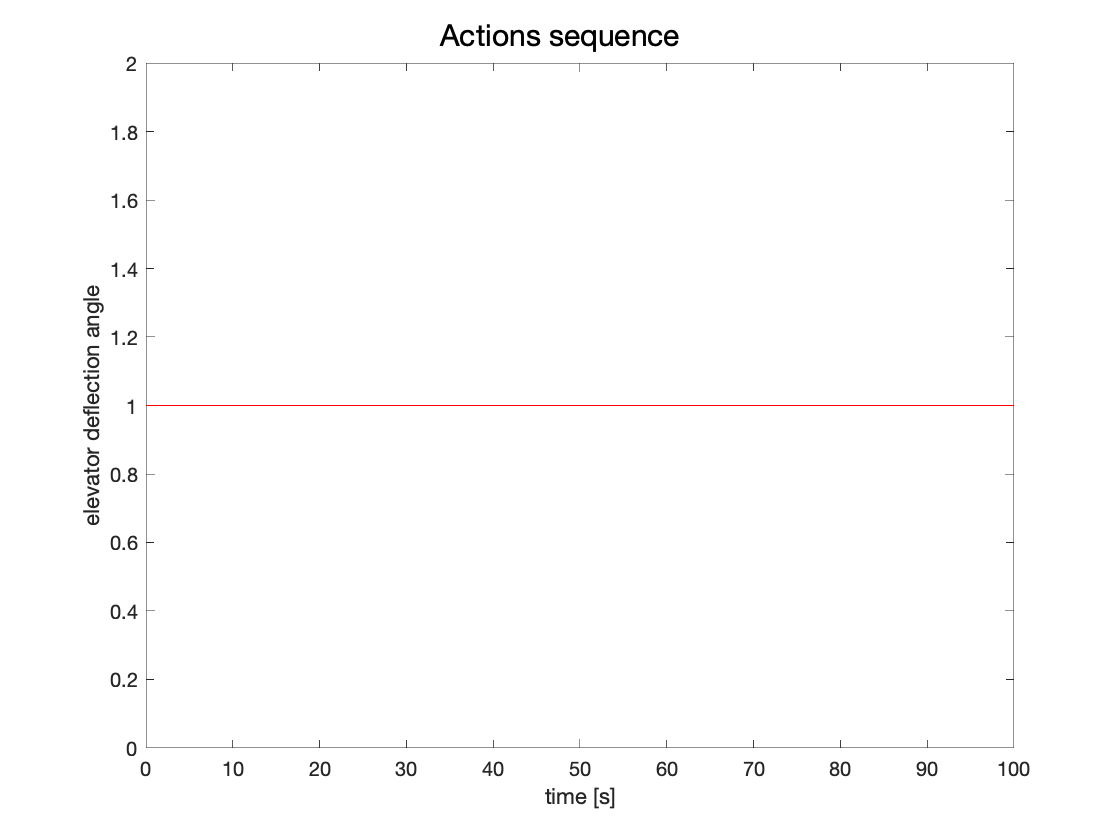

figure
sgtitle("Actions sequence")
plot(linspace(0,T(1)*time_res,T(1)),u_seq,'r')
xlabel("time [s]")
ylabel("elevator deflection angle")

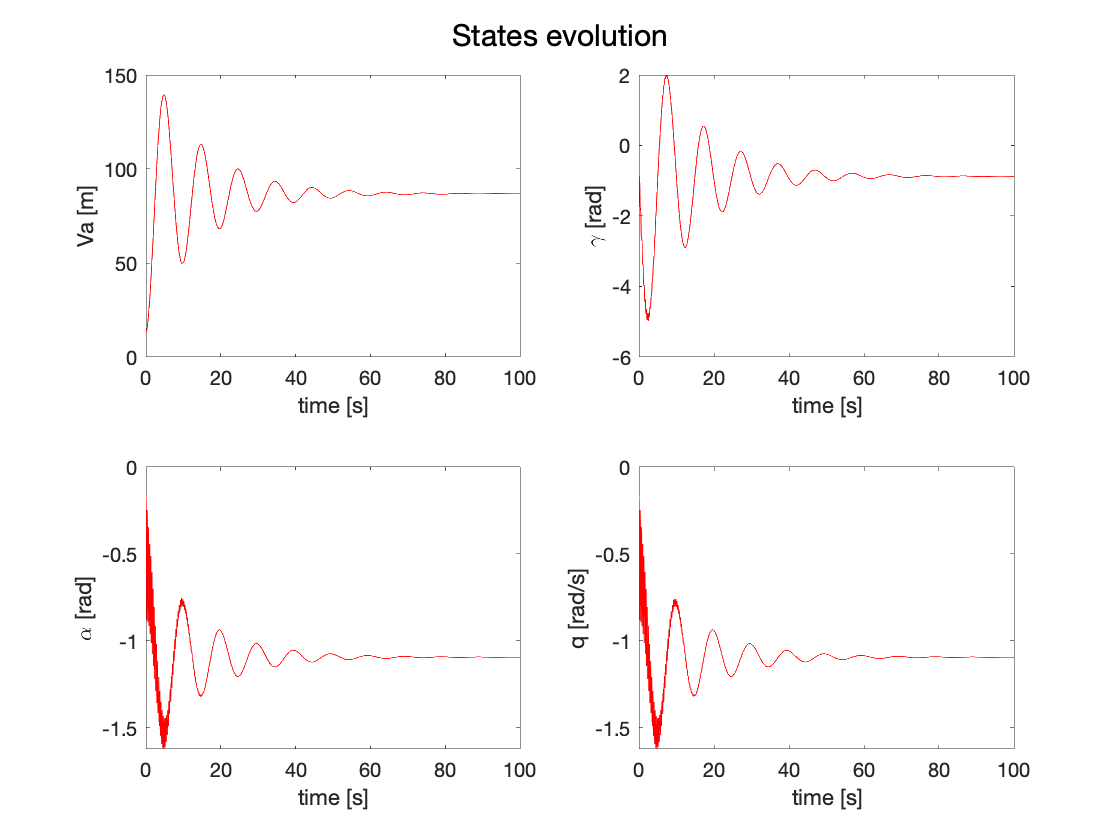


figure
sgtitle("States evolution")
subplot(2,2,1)
plot(linspace(0,T(1)*time_res,T(1)),X(1,2:end),'r')
xlabel("time [s]")
ylabel("Va [m]")

subplot(2,2,2)
plot(linspace(0,T(1)*time_res,T(1)),X(4,2:end),'r')
xlabel("time [s]")
ylabel("\gamma [rad]")

subplot(2,2,3)
plot(linspace(0,T(1)*time_res,T(1)),X(2,2:end),'r')
xlabel("time [s]")
ylabel("\alpha [rad]")

subplot(2,2,4)
plot(linspace(0,T(1)*time_res,T(1)),X(2,2:end),'r')
xlabel("time [s]")
ylabel("q [rad/s]")

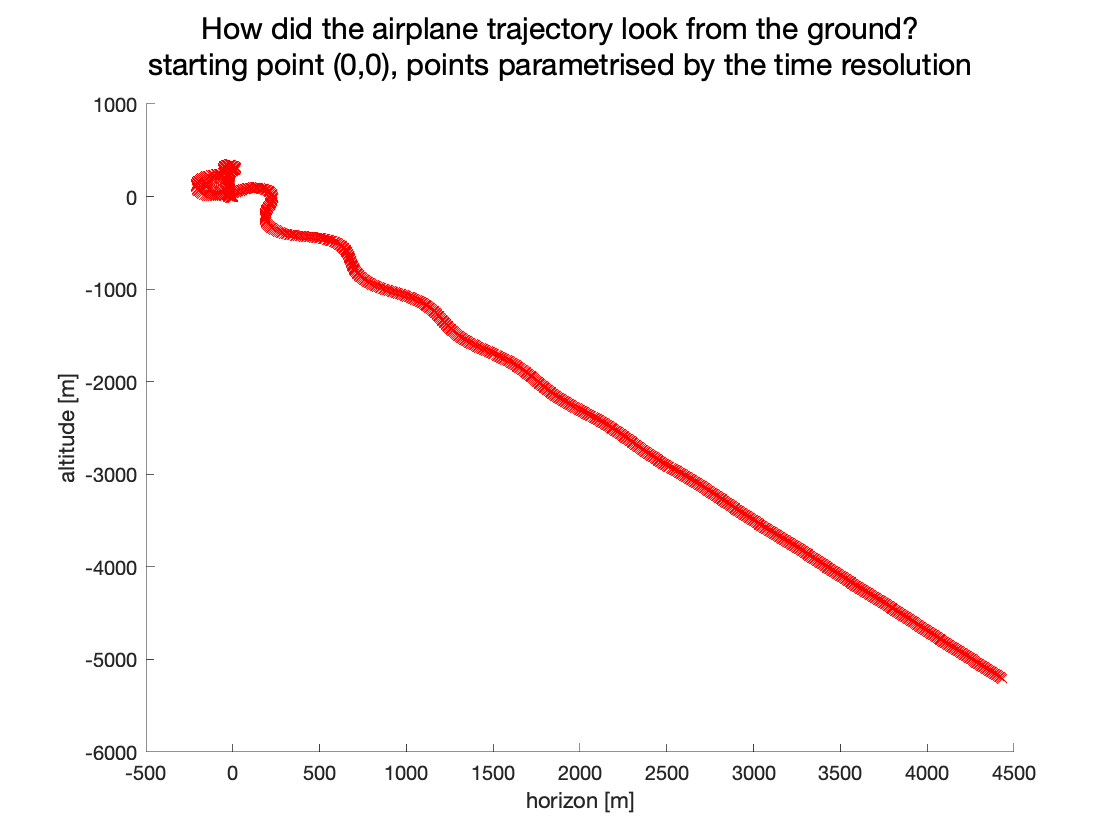


figure
sgtitle(["How did the airplane trajectory look from the ground?"; ...
    "starting point (0,0), points parametrised by the time resolution"])
subplot(1,1,1)
scatter(cumsum(X(1,:).*cos(X(4,:))*time_res),cumsum(X(1,:).*sin(X(4,:))*time_res),'r',"x")
xlabel("horizon [m]")
ylabel("altitude [m]")

Similar to sent results.

Let's try with zeros

clear
clc

time_res=.1; %time resolution, in seconds
x_s=[12.4573, -0.888532, 1.38132e-08, -0.164542]'; % initial condition
u_seq=zeros(1000,1); %actions sequence (step response)
T=size(u_seq);
X=x_s;
for j=1:T(1)
    u_s=u_seq(j,1);
    x_ns=Interact_with_aircraft(x_s,u_s,time_res);
    X=[X x_ns];
    x_s=x_ns;
end

Visualize samples:

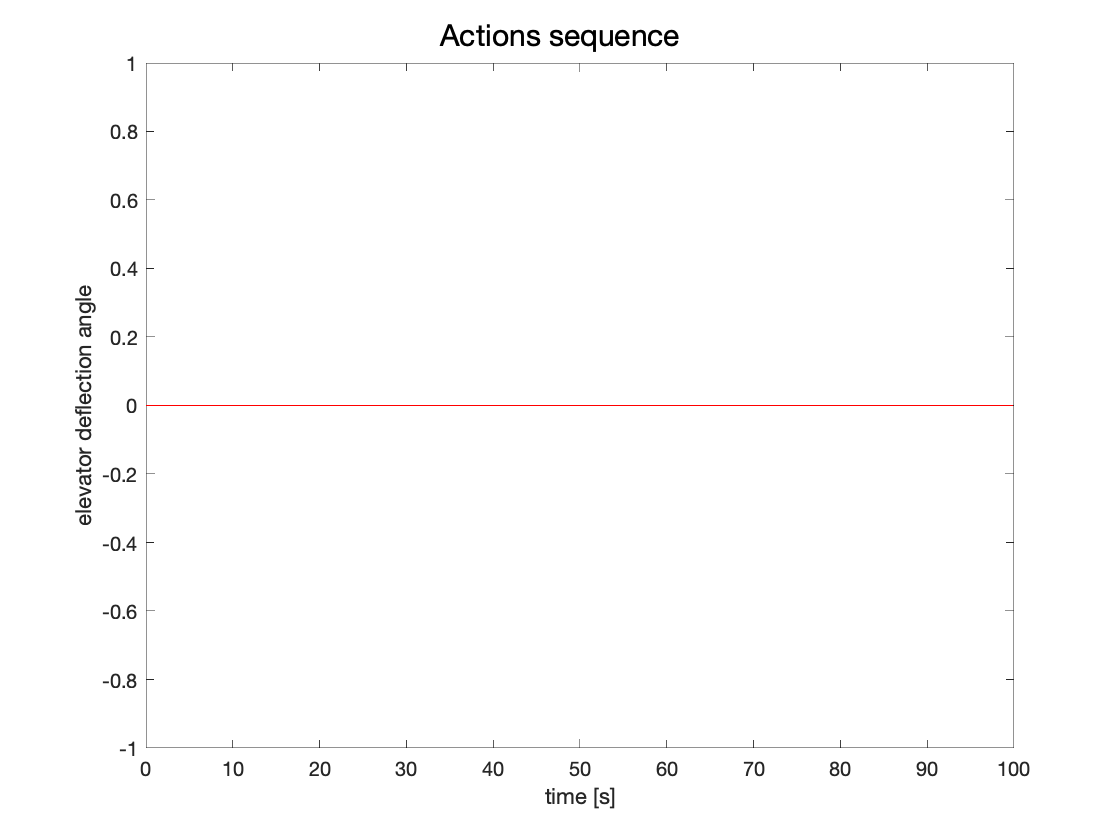

figure
sgtitle("Actions sequence")
plot(linspace(0,T(1)*time_res,T(1)),u_seq,'r')
xlabel("time [s]")
ylabel("elevator deflection angle")

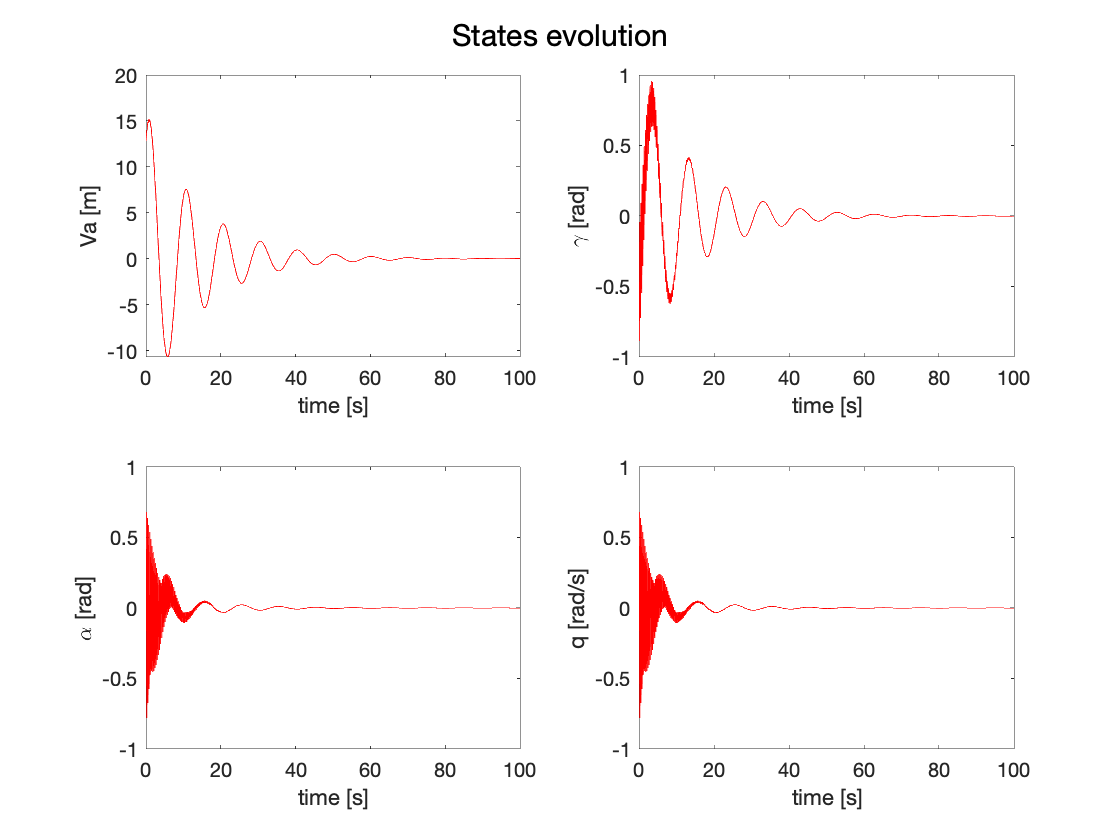


figure
sgtitle("States evolution")
subplot(2,2,1)
plot(linspace(0,T(1)*time_res,T(1)),X(1,2:end),'r')
xlabel("time [s]")
ylabel("Va [m]")

subplot(2,2,2)
plot(linspace(0,T(1)*time_res,T(1)),X(4,2:end),'r')
xlabel("time [s]")
ylabel("\gamma [rad]")

subplot(2,2,3)
plot(linspace(0,T(1)*time_res,T(1)),X(2,2:end),'r')
xlabel("time [s]")
ylabel("\alpha [rad]")

subplot(2,2,4)
plot(linspace(0,T(1)*time_res,T(1)),X(2,2:end),'r')
xlabel("time [s]")
ylabel("q [rad/s]")

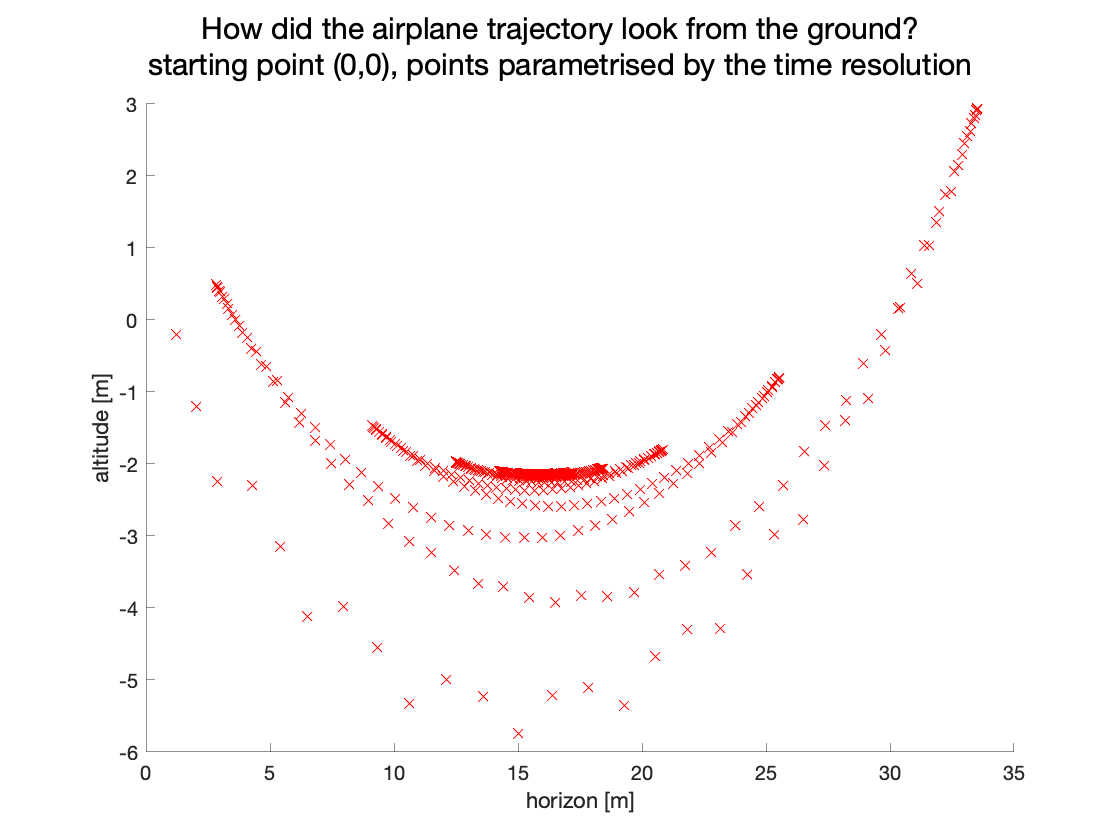


figure
sgtitle(["How did the airplane trajectory look from the ground?"; ...
    "starting point (0,0), points parametrised by the time resolution"])
subplot(1,1,1)
scatter(cumsum(X(1,:).*cos(X(4,:))*time_res),cumsum(X(1,:).*sin(X(4,:))*time_res),'r',"x")
xlabel("horizon [m]")
ylabel("altitude [m]")

Weird solution, possibly as the state-model representation by itself does not avoid incongruences such as that Va (norm velocity) turns negative. 

Acquired experience: To start collecting points we can randomize aircraft states and only do a one-step random action to collect next state. This way, we should avoid unusual states such as negative Va values. Bounds to generate random state values and actions must be defined. I need to study a little bit to familiarize with the reconstruction of A and B from samples.

clear

## Set up the third model:

Ac_uw = [ 
-0.274288 -0.217785  0.888532  -9.67355;
  -2.2507   -9.7801   12.4573   1.60623;
-0.534138   -7.4919  -18.9315         0;
        0         0         1         0];
Bc_uw = [ 
         0;
         0;
  -102.612;
         0];
% Discretized system
Ts = 0.1;   % =time_res;
A_nom_uw = eye(4) + Ts*Ac_uw;
B_nom_uw = Ts*Bc_uw;    

% State constraints; Hx*x <= bx
Hx=[1 0 0 0;...
    -1 0 0 0;...
    0 1 0 0;...
    0 -1 0 0;...
    0 0 1 0;...
    0 0 -1 0;...
    0 0 0 1;...
    0 0 0 -1];
bx=[inf; inf; inf; inf; inf; inf; inf; inf]; %irrelevant at the moment

% Input constraints; Hu*u <= bu
Hu=[1;-1];
bu=[inf;inf];   %irrelevant at the moment

% Instantiate System
sys_uw = LinearSystem(A_nom_uw, B_nom_uw, Hx, bx, Hu, bu);


## Set Membership Estimation for dimensional derivatives

State-space model with dimensional derivatives (like Johannes' 3rd linear model):  


$$$\left(\begin{array}{c}\dot{v}_x \\ \dot{v}_z \\ \dot{q} \\ \dot{\theta} \end{array}\right)=\left(\begin{array}{ccccc}X_{u} & X_{w} & X_{q} & -g \cos \theta^{*} \\ Z_{u} & Z_{w} & Z_{q} & -g \sin \theta^{*}  \\ M_{u} & M_{w} & M_{q} & 0  \\ 0 & 0 & 1 & 0 \end{array}\right)\left(\begin{array}{c}v_x \\ v_z \\ q \\ \theta \end{array}\right) + \left(\begin{array}{c} X_{\delta_e} \\ Z_{\delta_e} \\ M_{\delta_e} \\0 \end{array}\right)\delta_e$$$


You can see here that we have 12 so called dimensional derivatives which are uncertain. I think that we should try to improve the estimation of these derivatives using the set membership method. The other values in the A and B matrices are known: $g$ is the gravitational constant and $\theta^{*}$ is the pitch angle at the trim point. 

We can describe the uncertain derivatives for example with $\Delta X_u=X_{u,true} -X_u$. Then like in the EECI exercise we can split the matrices up into A and B with the initially estimated values:

AB = [sys_uw.A,sys_uw.B];

 and 12 matrices for each uncertainty $\theta = [\Delta X_u, \Delta X_w, \Delta X_q, \Delta X_{\delta_e}, \Delta Z_u, \Delta Z_w, \Delta Z_q, \Delta Z_{\delta_e}, \Delta M_u, \Delta M_w, \Delta M_q, \Delta M_{\delta_e}]^{T}$

ABi = zeros(4,5,2);
ABi(1,1,1) = Ts;        % Delta X_u
ABi(1,2,2) = Ts;        % Delta X_w
ABi(1,3,3) = Ts;        % Delta X_q
ABi(1,5,4) = Ts;        % Delta X_delta_e
ABi(2,1,5) = Ts;        % Delta Z_u
ABi(2,2,6) = Ts;        % Delta Z_w
ABi(2,3,7) = Ts;        % Delta Z_q
ABi(2,5,8) = Ts;        % Delta Z_delta_e
ABi(3,1,9) = Ts;        % Delta M_u
ABi(3,2,10) = Ts;        % Delta M_w
ABi(3,3,11) = Ts;        % Delta M_q
ABi(3,5,12) = Ts;        % Delta M_delta_e

Next we define initial bounds on the parameters starting with for example 20% uncertainty on each parameter:

% initial bounds on parameters
uncert = 0.2;
H_theta=[eye(12); -eye(12)];
h_theta=uncert*abs([Ac_uw(1,1),Ac_uw(1,2),Ac_uw(1,3),Bc_uw(1,1),...
                    Ac_uw(2,1),Ac_uw(2,2),Ac_uw(2,3),Bc_uw(2,1),...
                    Ac_uw(3,1),Ac_uw(3,2),Ac_uw(3,3),Bc_uw(3,1)])';
h_theta(13:24) = h_theta(1:12);

% define initial paramter set
Omega{1} = Polyhedron(H_theta,h_theta);

Using the system model


$$x(k\!+\!1) = [A,\, B] \left[\matrix{ x(k) \cr u(k) }\right] + \phi(x,u)  \theta  + w(k)$$


from the EECI course we need some additive disturbance $w(k) \in \bar{\mathcal{W}}$. I tried a little bit around and a value of 0.05 worked well. 

w_max = 0.05;
% Define additive polytopic uncertainty description
Hw = [1 0 0 0; -1 0 0 0; ...
      0 1 0 0; 0 -1 0 0;...
      0 0 1 0; 0 0 -1 0;...
      0 0 0 1; 0 0 0 -1];
hw = w_max*ones(8,1);
W = Polyhedron(Hw,hw);

Now we can just use the set membership class.

% instantiate set membership estimator
sm = SetMembership(Omega{1},W,ABi,AB);

#### Test Set Membership estimation

For the true system one can use for example the given one plus 10% on each derivative:

Ac_true = Ac_uw;
Bc_true = Bc_uw;
Ac_true(1:3,1:3) = 1.1* Ac_true(1:3,1:3);
Bc_true(1:3) = 1.1 * Bc_true(1:3);
A_true = eye(4) + Ts*Ac_true;    % discretized
B_true = Ts*Bc_true;

Now we can simulate the system and do some estimation.

x = [12.4573, -0.888532, 1.38132e-08, -0.164542]'; % trim point
u_seq=[ones(30,1); -ones(20,1); ones(10,1); -ones(10,1)]; %actions sequence (3-2-1-1)
T=length(u_seq);
theta_hat = []; % estimated values


for i=1:T
    u = u_seq(i);
    xp = A_true*x + B_true*u;   % simulate one step 
    
    [Omega{i+1},D{i}] = sm.update(xp, x, u);    % update set membership
    
    theta_hat = [theta_hat, sm.theta_hat];  % estimate parameter (center of the estimated set)
    
    
    % plotting the sets (if only two parameters are uncertain):
%         if ~D{i}.isBounded 
%             D{i} = Polyhedron('A',D{i}.A, 'b', D{i}.b, 'lb', -100*ones(2,1), 'ub', 100*ones(2,1));
%         end
%         subplot(ceil(T/2),2,i)
%         hold off
%         plot(D{i},'color','b','alpha',0.1)
%         hold on
%         plot(Omega{i},'alpha',0.1)
%         plot(Omega{i+1})
%         xlim(1.2*[-h_theta(1), h_theta(3)])
%         ylim(1.2*[-h_theta(2), h_theta(4)])
%         title(['k=', int2str(i)])

    
    
    x=xp;   
end

Finally we can plot the estimated parameters and check, if they converge to the true value.

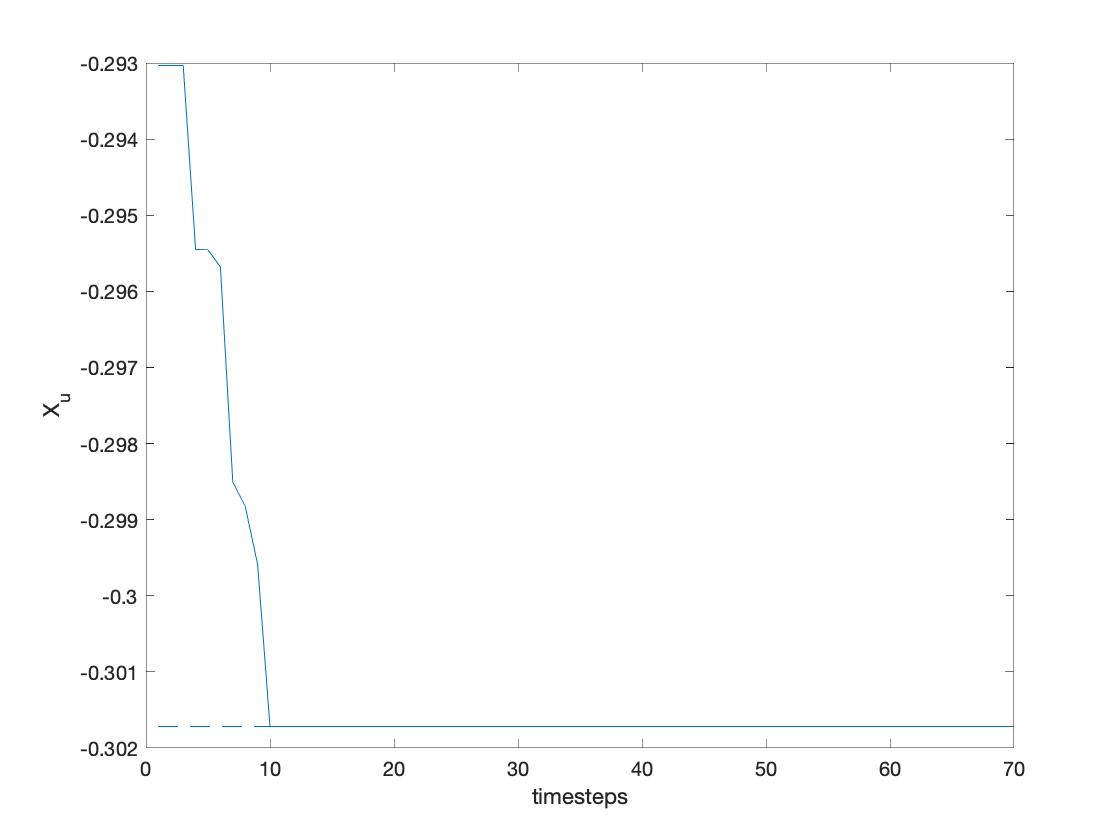

figure;
plot(1:1:T, Ac_uw(1,1)*ones(1,T)+theta_hat(1,:), 1:1:T, Ac_true(1,1)*ones(T), '--');
xlabel("timesteps")
ylabel("X_u")

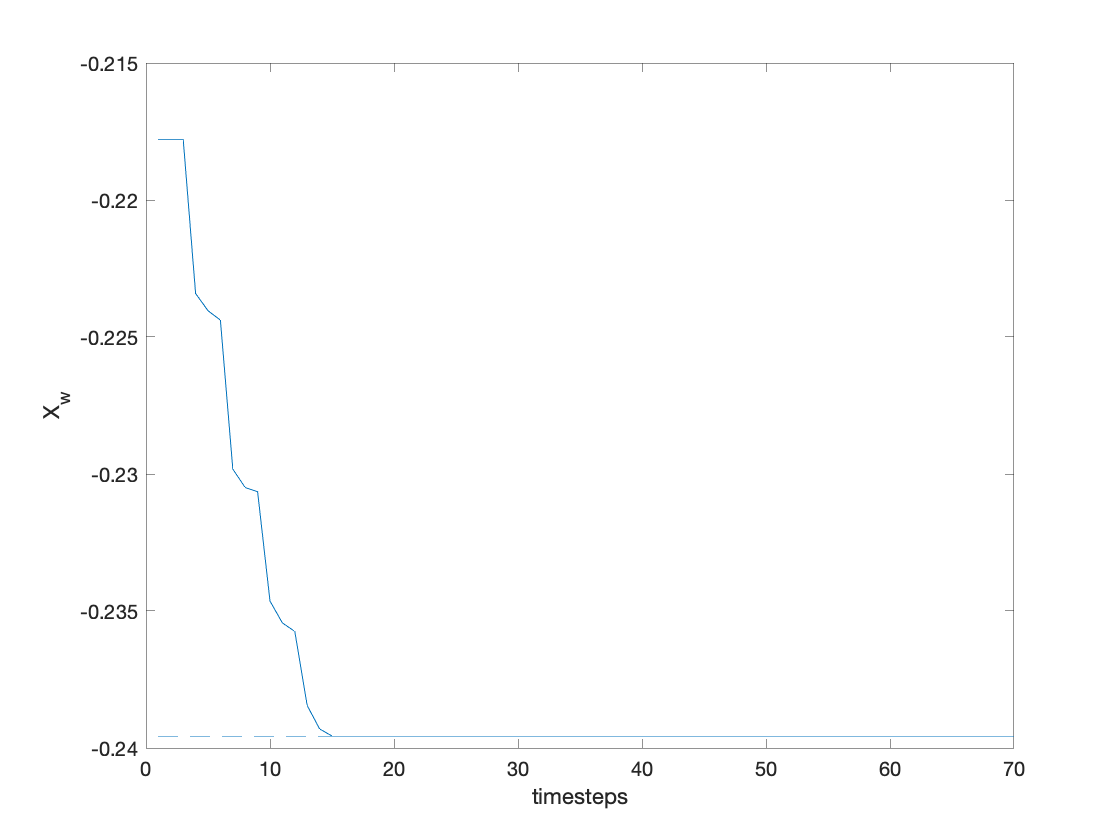

figure;
plot(1:1:T, Ac_uw(1,2)*ones(1,T)+theta_hat(2,:), 1:1:T, Ac_true(1,2)*ones(T), '--');
xlabel("timesteps")
ylabel("X_w")

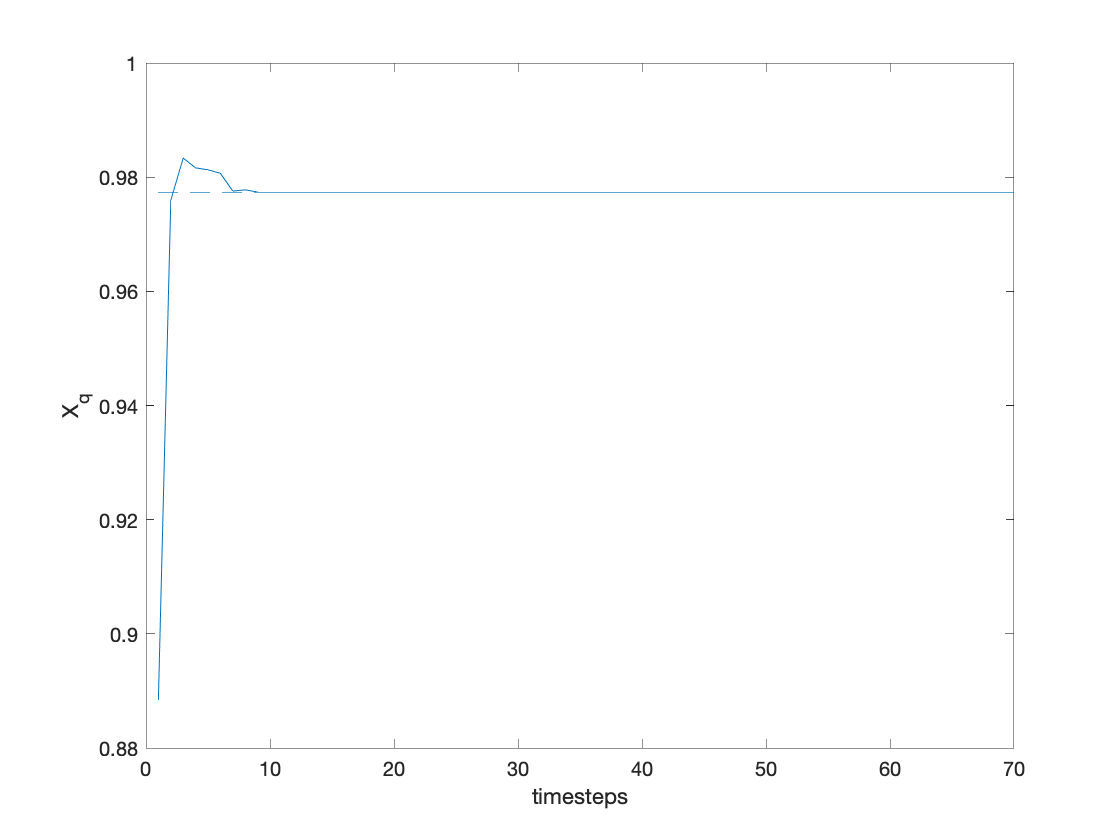

figure;
plot(1:1:T, Ac_uw(1,3)*ones(1,T)+theta_hat(3,:), 1:1:T, Ac_true(1,3)*ones(T), '--');
xlabel("timesteps")
ylabel("X_q")

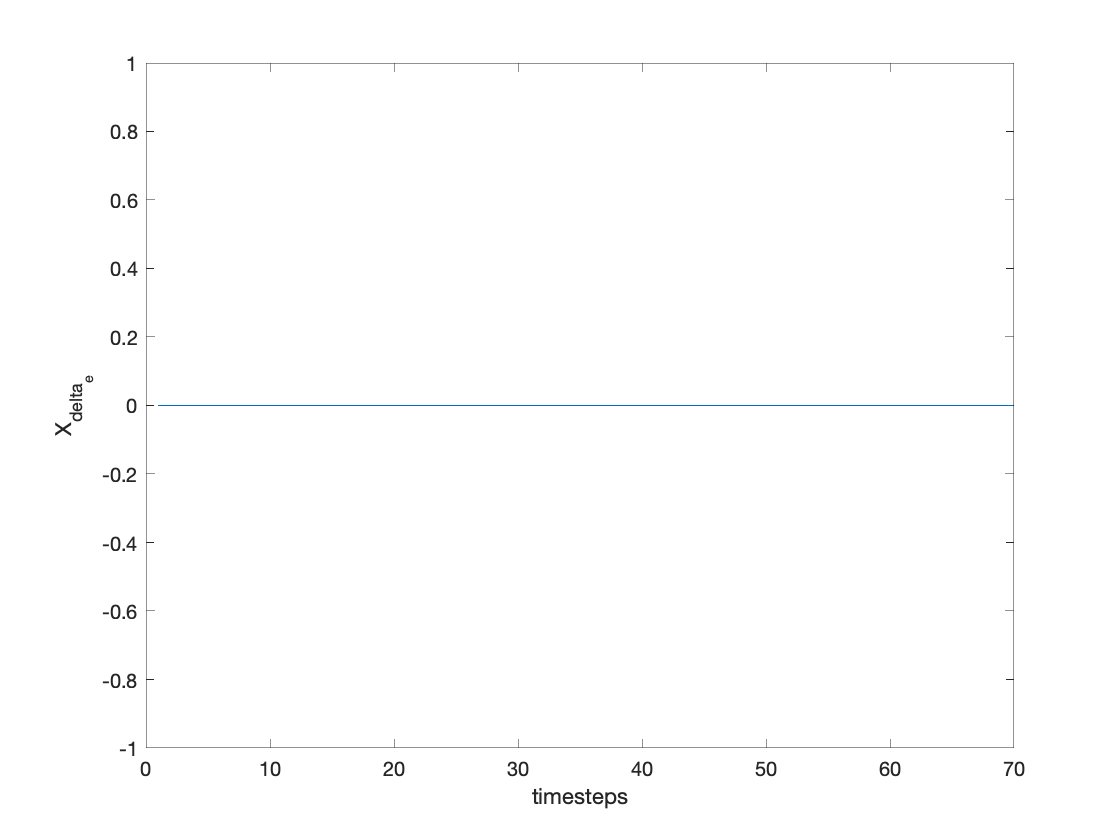

figure;
plot(1:1:T, Bc_uw(1,1)*ones(1,T)+theta_hat(4,:), 1:1:T, Bc_true(1,1)*ones(T), '--');
xlabel("timesteps")
ylabel("X_{delta_e}")

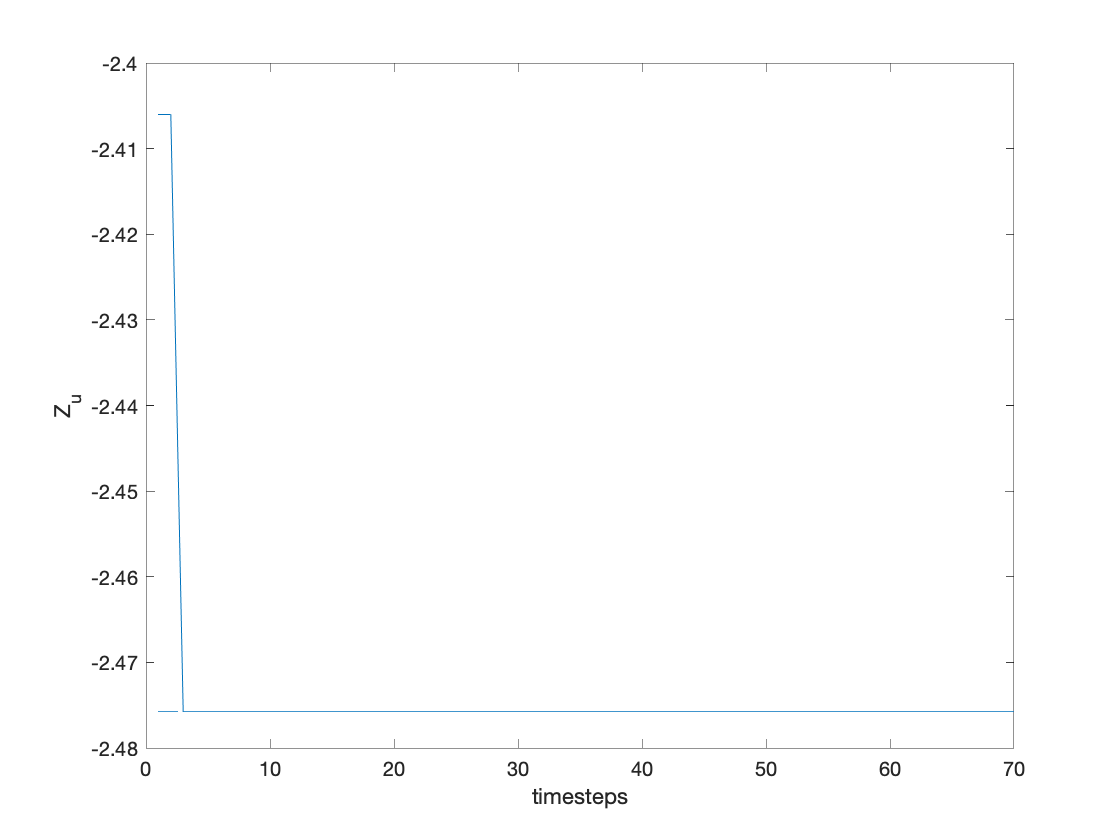

figure;
plot(1:1:T, Ac_uw(2,1)*ones(1,T)+theta_hat(5,:), 1:1:T, Ac_true(2,1)*ones(T), '--');
xlabel("timesteps")
ylabel("Z_u")

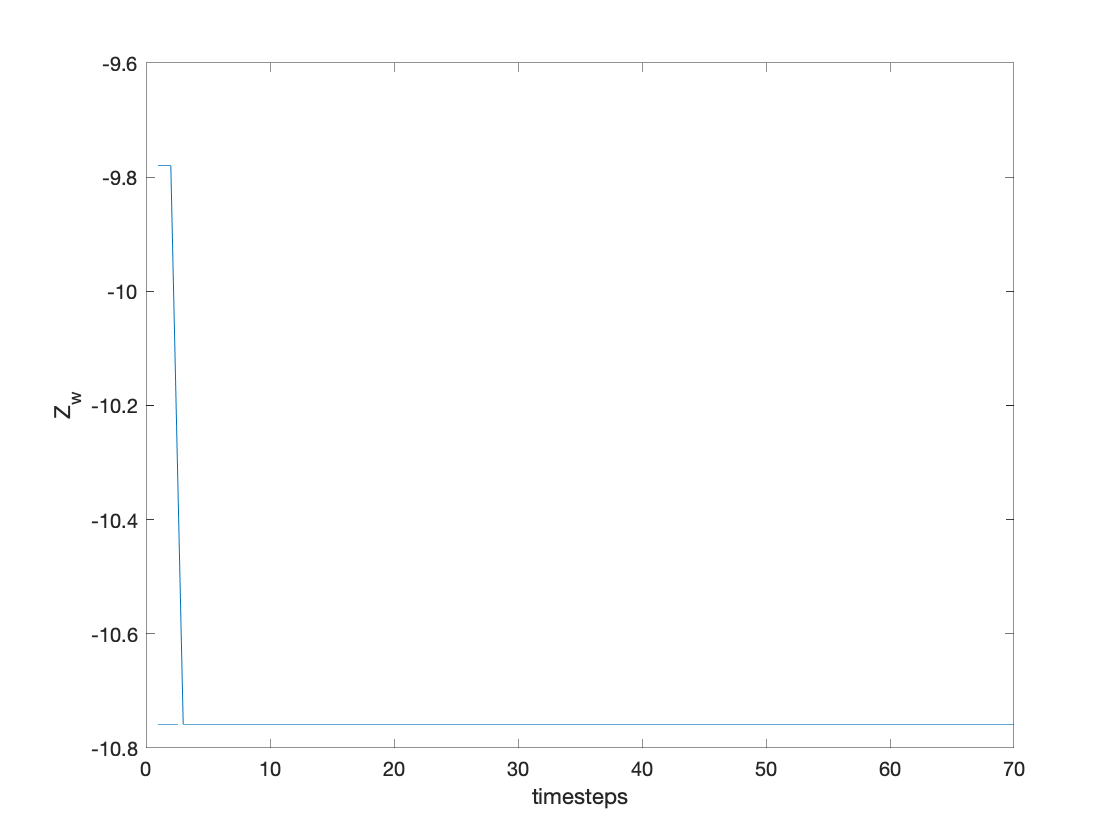

figure;
plot(1:1:T, Ac_uw(2,2)*ones(1,T)+theta_hat(6,:), 1:1:T, Ac_true(2,2)*ones(T), '--');
xlabel("timesteps")
ylabel("Z_w")

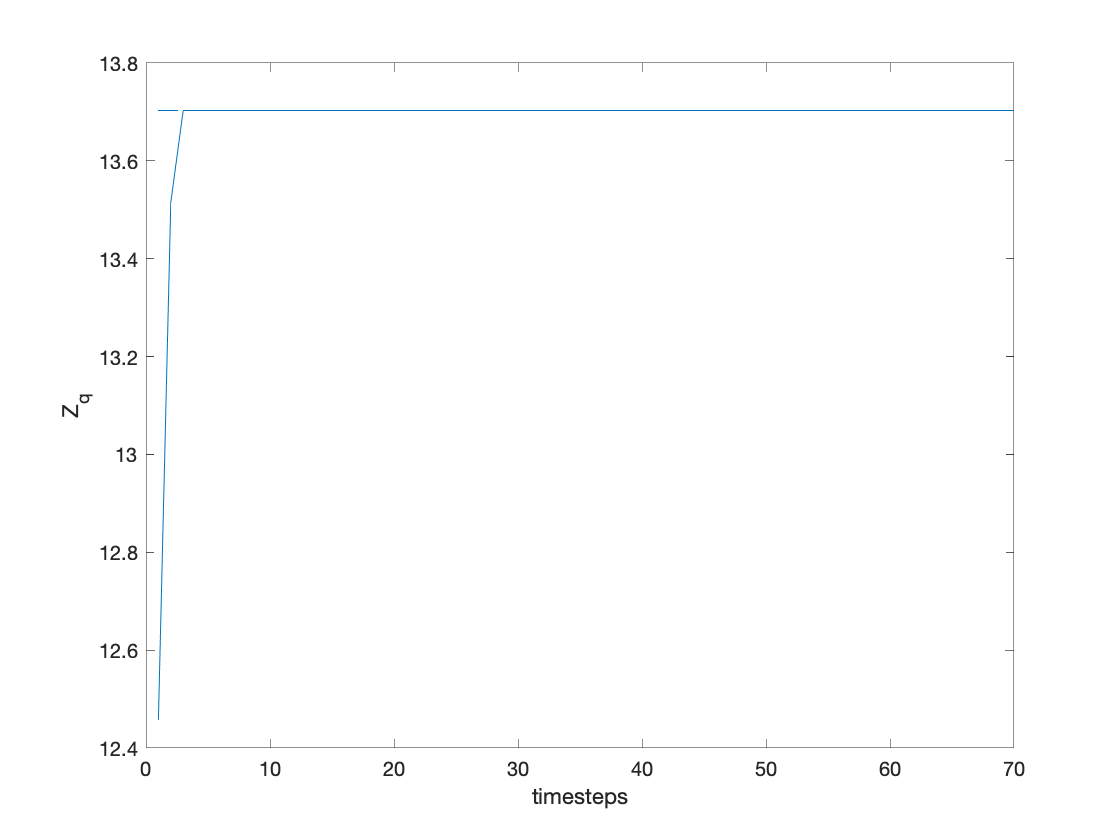

figure;
plot(1:1:T, Ac_uw(2,3)*ones(1,T)+theta_hat(7,:), 1:1:T, Ac_true(2,3)*ones(T), '--');
xlabel("timesteps")
ylabel("Z_q")

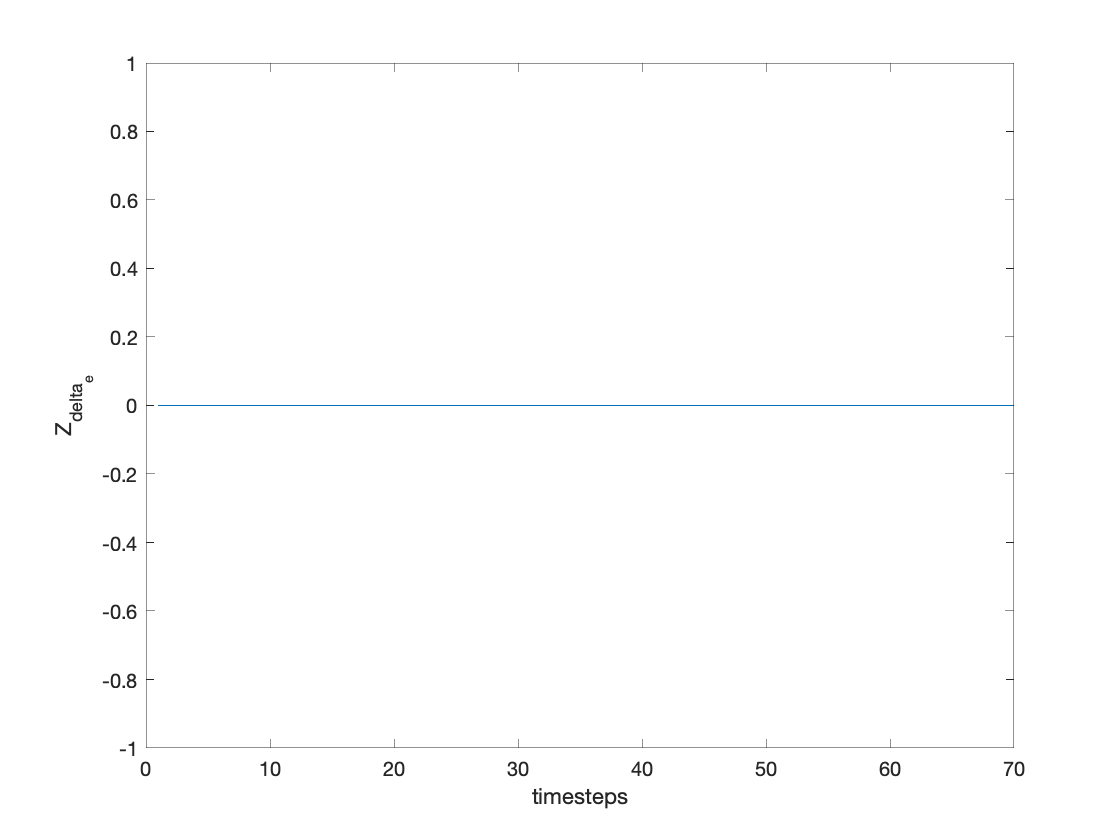

figure;
plot(1:1:T, Bc_uw(2,1)*ones(1,T)+theta_hat(8,:), 1:1:T, Bc_true(2,1)*ones(T), '--');
xlabel("timesteps")
ylabel("Z_{delta_e}")

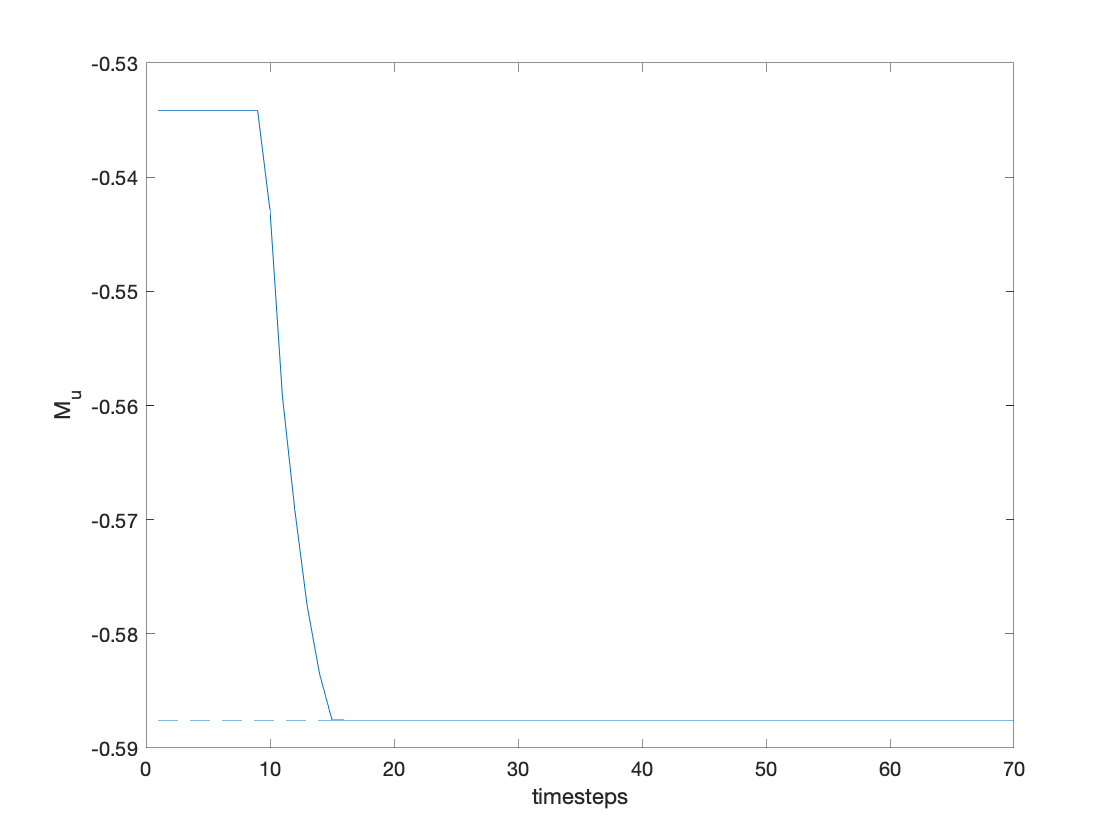

figure;
plot(1:1:T, Ac_uw(3,1)*ones(1,T)+theta_hat(9,:), 1:1:T, Ac_true(3,1)*ones(T), '--');
xlabel("timesteps")
ylabel("M_u")

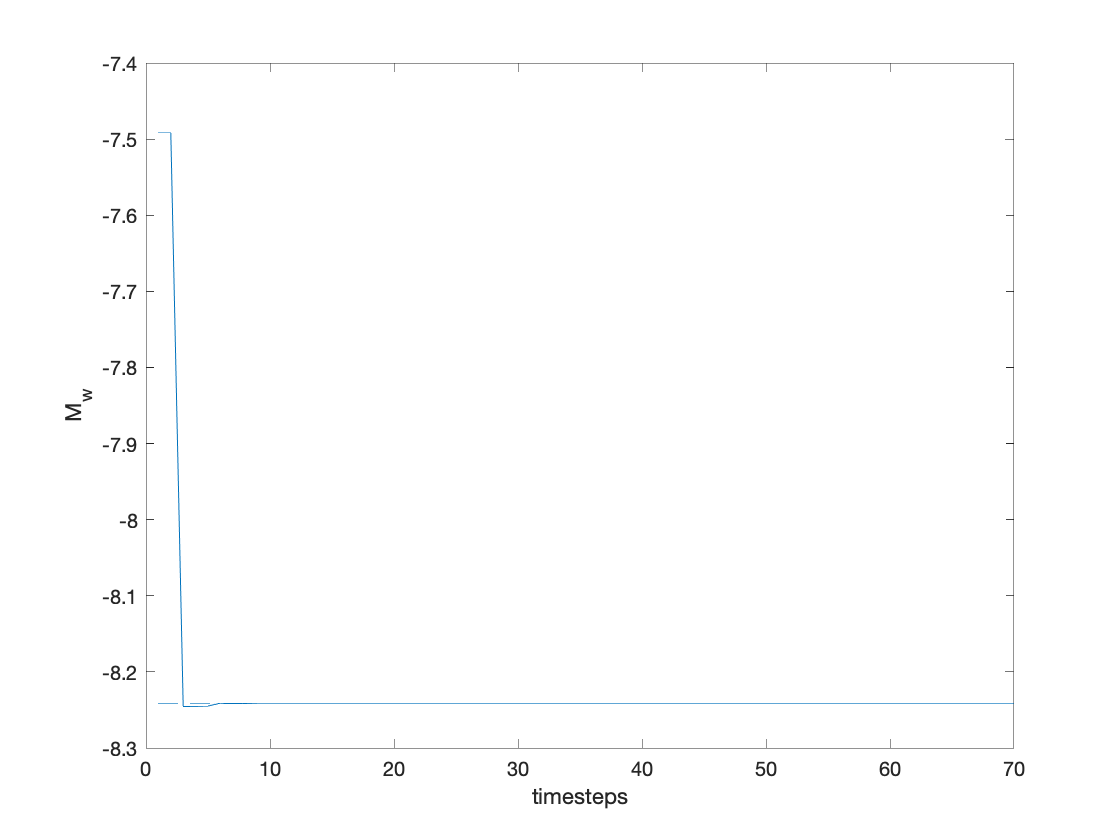

figure;
plot(1:1:T, Ac_uw(3,2)*ones(1,T)+theta_hat(10,:), 1:1:T, Ac_true(3,2)*ones(T), '--');
xlabel("timesteps")
ylabel("M_w")

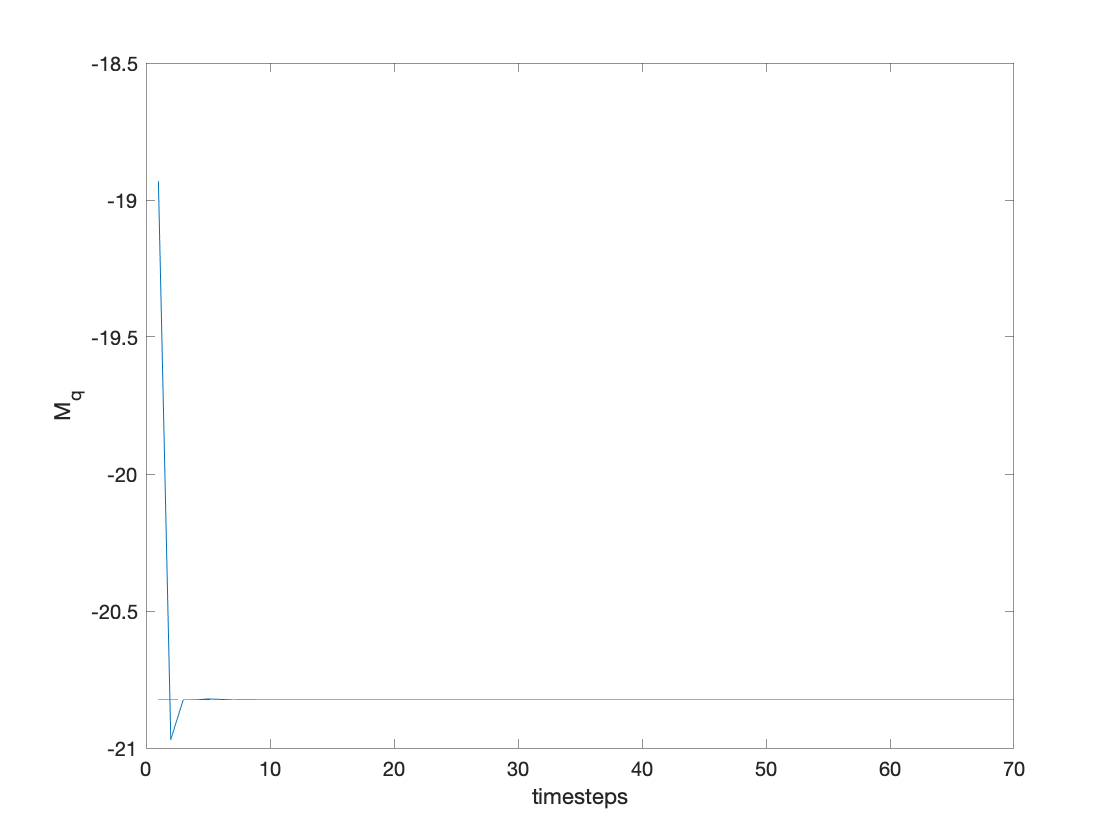

figure;
plot(1:1:T, Ac_uw(3,3)*ones(1,T)+theta_hat(11,:), 1:1:T, Ac_true(3,3)*ones(T), '--');
xlabel("timesteps")
ylabel("M_q")

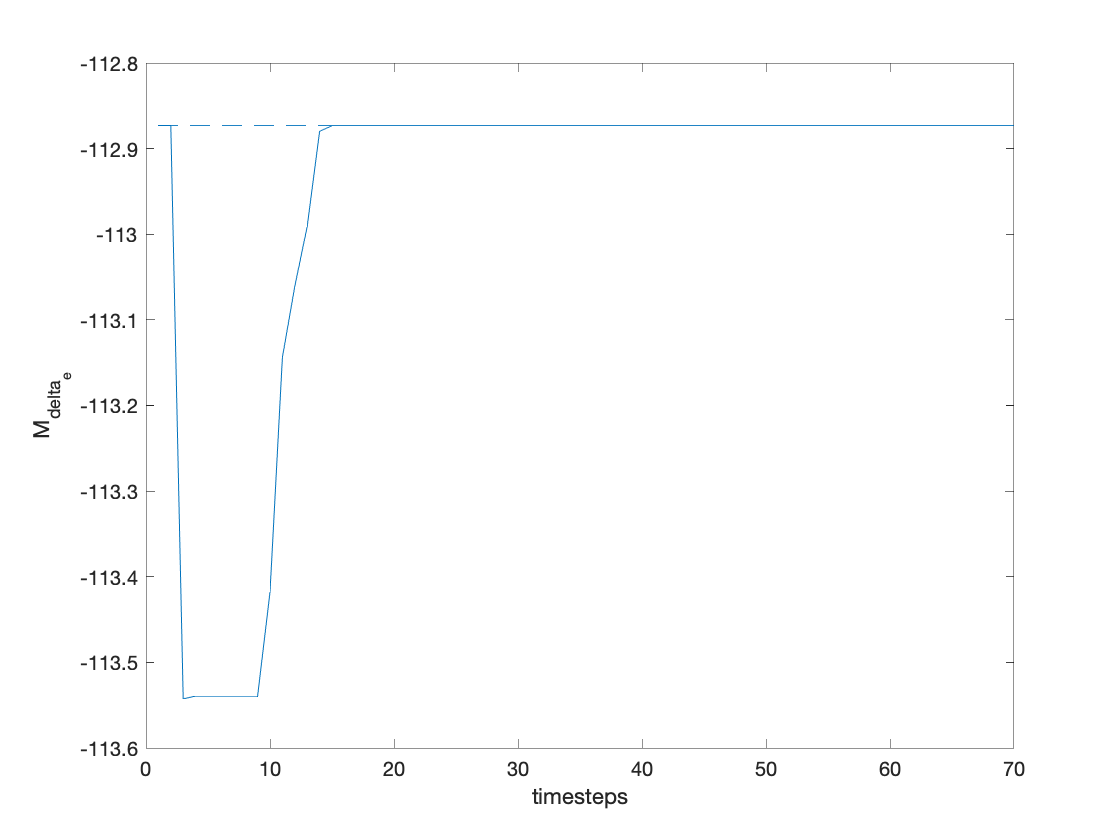

figure;
plot(1:1:T, Bc_uw(3,1)*ones(1,T)+theta_hat(12,:), 1:1:T, Bc_true(3,1)*ones(T), '--');
xlabel("timesteps")
ylabel("M_{delta_e}")